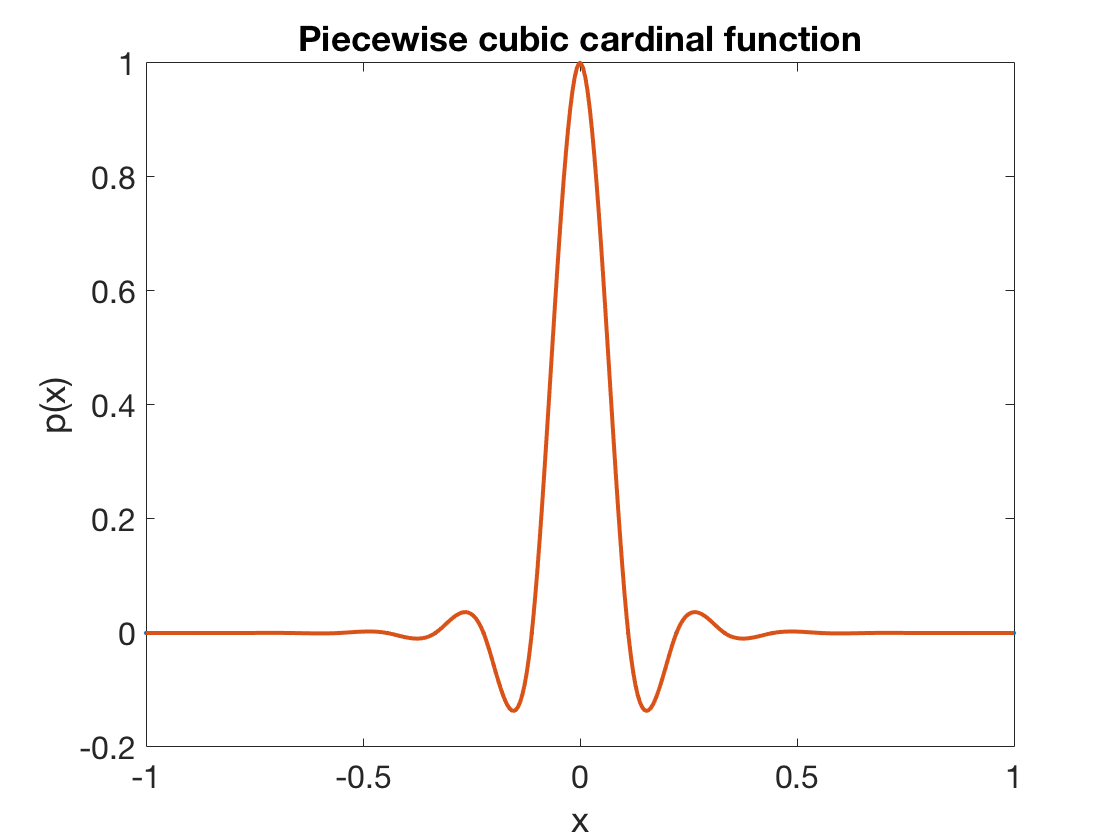

n = 18;
t = linspace(-1,1,n+1)';
y = [zeros(9,1);1;zeros(n-9,1)];  % 10th cardinal function
plot(t,y,'.'), hold on
x = linspace(-1,1,400)';
plot(x,interp1(t,y,x,'spline'))
title('Piecewise cubic cardinal function')   % ignore this line
xlabel('x'), ylabel('p(x)')   % ignore this line

The piecewise cubic cardinal function is nowhere greater than one in absolute value. This happens to be true for all the cardinal functions, ensuring a good condition number for the interpolation. But the story for global polynomials is very different.

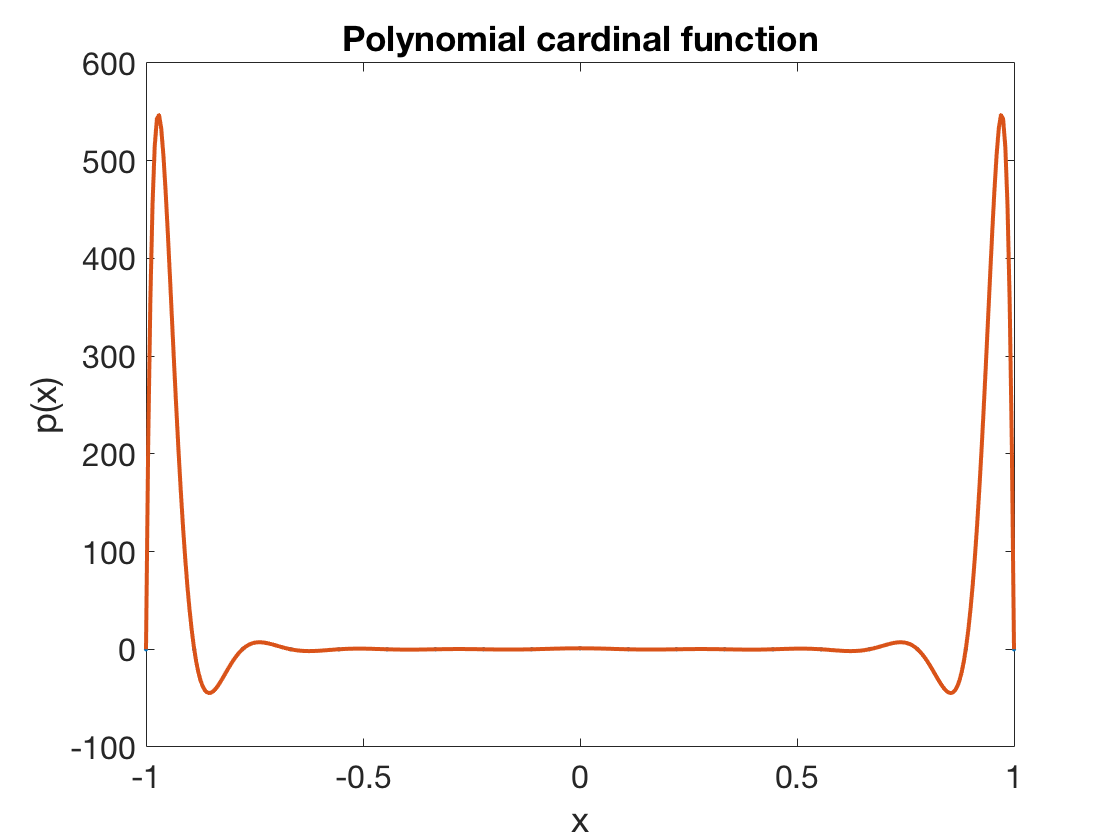

clf, plot(t,y,'.')    % ignore this line
c = polyfit(t,y,n);
hold on, plot(x,polyval(c,x))
title('Polynomial cardinal function')     % ignore this line
xlabel('x'), ylabel('p(x)')   % ignore this line

From the figure we can see that the condition number for polynomial interpolation on these nodes is at least 500. 